# Inverted Cart Pendulum

$\vec{x} = \pmatrix{\bf{q_1} \cr \bf{q_2} \cr \bf{\dot{q_1}} \cr \bf{\dot{q_2}}} $     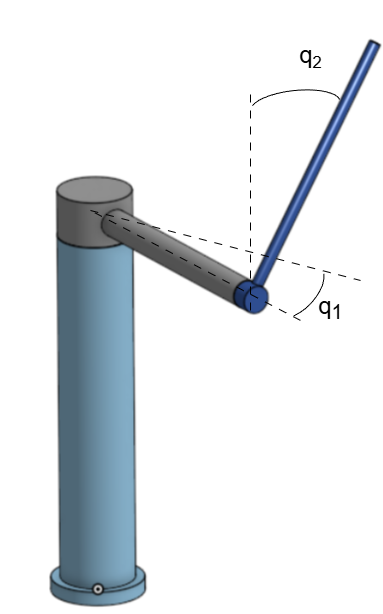

see MATLAB for **Solve Differential Algebraic Equations (DAEs)**

**see **[YouTube](https://www.youtube.com/watch?v=hAI8Ag3bzeE&t=210s)** video**

## Initialization

clearvars;

doNonLinearSolve = 1;
doLinearization = 1;

## **Setup Geometry**

### **Setup Symbolics**

syms m_h L_h m_p Lcm_p Lcm_h g T_h t real
syms q [2 1] real
syms qd [2 1] real
syms qdd [2 1] real
syms psi(t) phi(t)

state = [q;qd];
dstate = [qd;qdd];

### **Masses - position and velocity**

rHead = rotateZ(-q1)*Lcm_h*[1;0;0];
rPend = +rotateZ(-q1)*(L_h*[1;0;0] + rotateX(-q2)*Lcm_p*[0;0;-1]);

vHead = jacobian(rHead, q)*qd;
vPend = jacobian(rPend, q)*qd;

### **Kinetic and Potential Energy of system (m and M)**

T = 1/2*m_h*(vHead.'*vHead) + 1/2*m_p*(vPend.' * vPend);
V = m_p*rPend'*[0;0;-g];
u = [T_h;0];
L = T - V;

### **Deriving eom`s in generalized coordinates**


$$\frac{d}{dt}\Big( \frac{\partial T}{\partial \dot q} \Big) -\frac{\partial T}{\partial q}  +  \frac{\partial V}{\partial q}=\Sigma F \\
L \equiv E_k - E_p$$


dT_dq = gradient(T,q);
dV_dq = gradient(V,q);
dT_dqd = gradient(T, qd);
ddt_dT_dqd = jacobian(dT_dqd, q)*qd + jacobian(dT_dqd, qd)*qdd;

eqns = simplify(ddt_dT_dqd - dT_dq + dV_dq) == u;

## Non-Linear Simulation

if doNonLinearSolve

### subs to real coordinates

    eqns = subs(eqns, {q1, q2, qd1, qd2, qdd1, qdd2}, {psi, phi, diff(psi), diff(phi), diff(psi, t, 2), diff(phi, t, 2)});

### **Differential Algebraic Equations**

    vars = [psi;phi];
    [DAEs, DAEvars] = reduceDifferentialOrder(eqns, vars);
    [M_, F_] = massMatrixForm(DAEs, DAEvars);
    f = M_\F_;

**Defining free parameters**

    pDAEs = symvar(DAEs);
    pDAEvars = symvar(DAEvars);
    extraParams = setdiff(pDAEs, pDAEvars);
    f = odeFunction(f, DAEvars, extraParams);

### Solving

    iCond = [0.0; deg2rad(25); 0.0; 0.0];
    tInit = 0;
    tFinal = 10;
    tSpan = (tInit:0.01:tFinal)';

    opt = odeset('RelTol',10.0^(-7), 'AbsTol',10.0^(-7));

    
    J_h_val = 2886244 * 1e-9;
    m_h_val = 262.88/1000; %head link mass
    Lcm_h_val = sqrt(J_h_val / m_h_val);
    L_h_val = 357/1000; %head link length[mm]
   
    J_p_val = 1.829e6 * 1e-9;
    m_p_val = 72.742/1000; %pendulum link mass
    Lcm_p_val = sqrt(J_p_val/m_p_val);%pendulum link Center Of Gravity [mm]
    T_h = 0.0; %Motor Torque
    g_val = 9.81;
 

    extraParamsVals = [L_h_val Lcm_h_val Lcm_p_val T_h g_val m_h_val m_p_val] ;

    sol = ode45(@(t, y) f(t, y, extraParamsVals), tSpan, iCond, opt);


### Plotting Non-Linear Solution

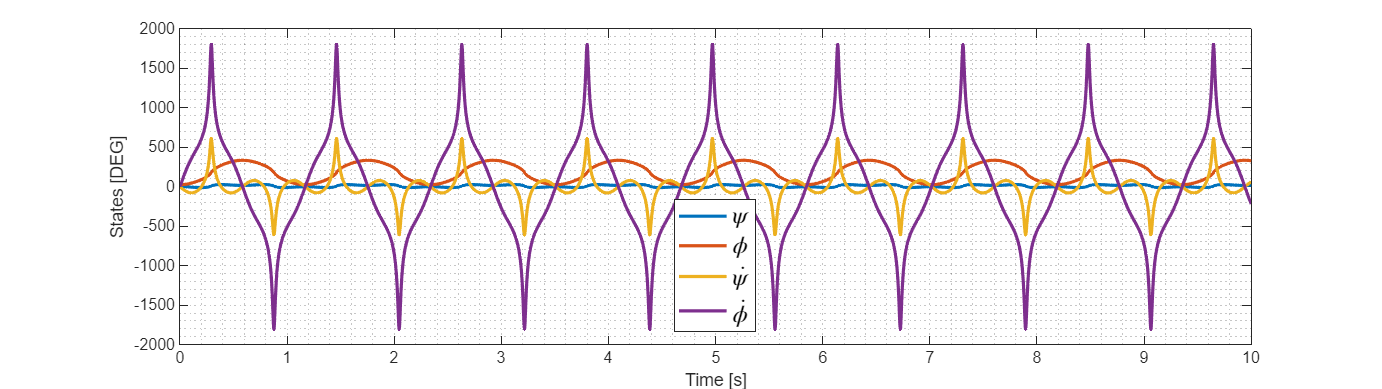

    figure('Units','normalized', 'Position',[0 0 0.6 0.3])

    plot(sol.x, rad2deg(sol.y), 'LineWidth',2), hold on

    legend({'$\psi$', '$\phi$', '$\dot{\psi}$', '$\dot{\phi}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15, 'ItemHitFcn',@clickLegendToHide);
    xlabel('Time [s]');
    ylabel('States [DEG]')
    grid minor
end

**Reducing order**

qdd_expr = solve(eqns, qdd);
fnames = fieldnames(qdd_expr);
dstate_expr = qd;

for ind = 1 : numel(fnames)
    dstate_expr(ind+2,1) = qdd_expr.(char(fnames(ind)));
end

Error using sym/privsubsasgn (line 1164)
Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

Error in indexing (line 1019)
                C = privsubsasgn(L,R,inds{:});

simplify(dstate_expr)

**Linearization**

1st fixed point - pendulum looking up

fixedPnt_up = zeros(4,1);
A_up = simplify(subs(jacobian(dstate_expr, state), state, fixedPnt_up))
B_up = simplify(subs(jacobian(dstate_expr, u(u~=0)), state, fixedPnt_up))

2nd point - pendulum looking down

fixedPnt_dwn = [0;pi;0;0];
A_dwn = simplify(subs(jacobian(dstate_expr, state), state, fixedPnt_dwn))
B_dwn = simplify(subs(jacobian(dstate_expr, u(u~=0)), state, fixedPnt_dwn))

## Simulation

**Define free Parameters**

extraParams = union(symvar(A_up), symvar(B_up))
L_h_val = 0.1;
Lcm_h_val = 9.81;
Lcm_p_val = 3;
g = 9.81;
m_h_val = 0.0;
m_p_val = 0.3;

extraParamsVals = [L_h_val Lcm_h_val Lcm_p_val g m_h_val m_p_val];


**Going Numeric**

1st point

A_up_num = eval(subs(A_up, extraParams, extraParamsVals));
B_up_num = eval(subs(B_up, extraParams, extraParamsVals));
C_num = eye(size(A_up_num));
D_num = zeros(size(B_up_num));

sys_up = ss(A_up_num, B_up_num, C_num, D_num);

2nd point

A_dwn_num = eval(subs(A_dwn, extraParams, extraParamsVals));
B_dwn_num = eval(subs(B_dwn, extraParams, extraParamsVals));
sys_dwn = ss(A_dwn_num, B_dwn_num, C_num, D_num);

**Simulating**

iCond = [0.0; pi/8; 0.0; 0.0];
tInit = 0;
tFinal = 10;
tSpan = [tInit:0.01:tFinal]';
u_val = zeros(size(tSpan));

[sol_up, t_up] = initial(sys_up, iCond, tFinal);
[sol_dwn, t_dwn] = initial(sys_dwn, iCond, tFinal);

**Visualization**

system up - unstable

figure
plot(t_up, sol_up, 'LineWidth',2), hold on

legend({'y', '$\theta$', '$\dot{y}$', '$\dot{\theta}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15)
grid on

system down - stable

figure
plot(t_dwn, sol_dwn, 'LineWidth',2), hold on

legend({'y', '$\theta$', '$\dot{y}$', '$\dot{\theta}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15)
grid on

% save('LinearizedInvertedCartPend', 'A_dwn','B_dwn');